clear all;
syms x;
syms y;

%f = x .* exp(-x.^2 - y.^2);
f= 0.3*x+0.1*y+(-3.5+0.5*x.^2+0.5*y.^2).^2+100*x .* exp(-x.^2 - y.^2);

grad = gradient(f, [x, y])

$$grad = \begin{array}{l} \left(\begin{array}{c} 100\,\sigma_{1}-200\,x^{2}\,\sigma_{1}+2\,x\,\left(\frac{x^{2}}{2}+\frac{y^{2}}{2}-\frac{7}{2}\right)+\frac{3}{10}\\ 2\,y\,\left(\frac{x^{2}}{2}+\frac{y^{2}}{2}-\frac{7}{2}\right)-200\,x\,y\,\sigma_{1}+\frac{1}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$


sol = solve(grad, [x, y])

sol = struct with fields:
    x: 2.5972108266993937373276830669093
    y: 0.69762334627548936016766205597833



hes = hessian(f, [x, y])

$$hes = \begin{array}{l} \left(\begin{array}{cc} 400\,x^{3}\,\sigma_{1}-600\,x\,\sigma_{1}+3\,x^{2}+y^{2}-7 & 2\,x\,y-200\,y\,\sigma_{1}+400\,x^{2}\,y\,\sigma_{1}\\ 2\,x\,y-200\,y\,\sigma_{1}+400\,x^{2}\,y\,\sigma_{1} & x^{2}-200\,x\,\sigma_{1}+3\,y^{2}+400\,x\,y^{2}\,\sigma_{1}-7 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$


for i = 1:length(sol.x)
    solll = subs(hes, [x, y], [sol.x(i), sol.y(i)])
    all(0<double(eig(solll))) % if positive definite
    all(0>double(eig(solll))) % if negative definite
end

$$solll = \left(\begin{array}{cc} 17.662839396453802549702397857715 & 4.8836947948202315101723574151331\\ 4.8836947948202315101723574151331 & 1.1955338073414396106746007523621 \end{array}\right)$$

ans = logical
   0


ans = logical
   0


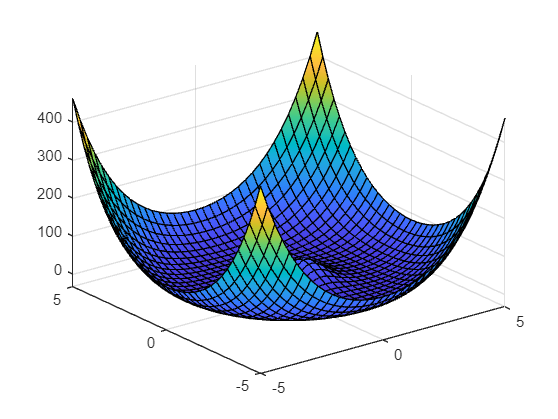

fsurf(f)